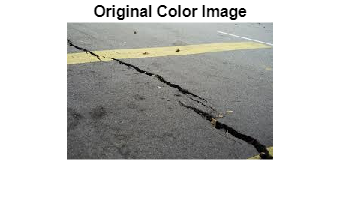

% Load the image
image = imread("C:\SEMESTER 5\IP\Project\ip1.jpg");
imshow(image);
title("Original Color Image");

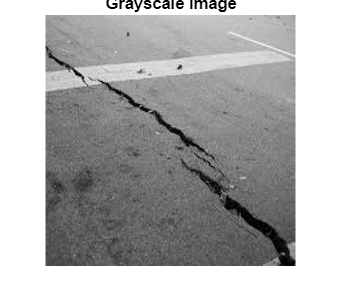


% Resize image for faster processing (optional)
image = imresize(image, [500, 500]);

% Convert the image to grayscale
grayImage = rgb2gray(image);
imshow(grayImage);
title("Grayscale Image");

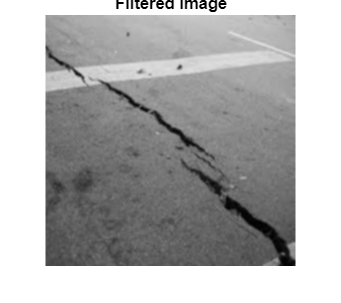


% Apply Gaussian blur to reduce noise, with a slightly lower sigma value
blurredImage = imgaussfilt(grayImage, 1.8);
imshow(blurredImage);
title("Filtered Image");

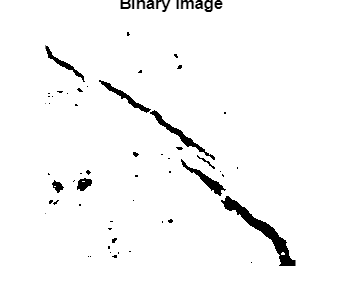


% Perform adaptive thresholding to separate cracks from background
binaryImage = imbinarize(blurredImage, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.4);
imshow(binaryImage);
title("Binary Image");

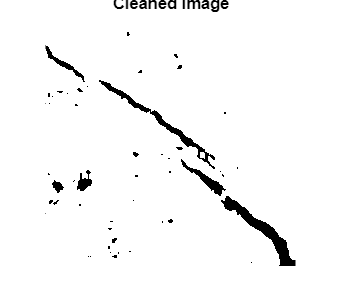


% Use morphological operations to clean up the image
se = strel('line', 10,90); % Using disk structuring element for better noise removal
cleanImage = imopen(binaryImage, se);
imshow(cleanImage);
title("Cleaned Image");

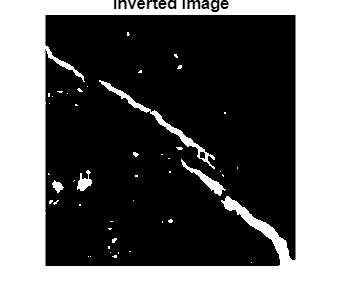


% Invert the binary image so cracks become white
invertedImage = imcomplement(cleanImage);
imshow(invertedImage);
title("Inverted Image");

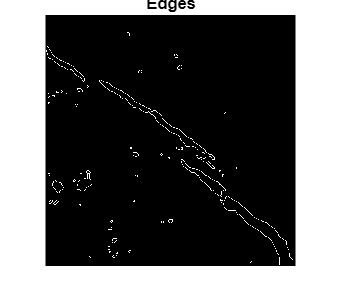


% Detect edges using the Canny method
edges = edge(invertedImage, 'canny');
imshow(edges);
title("Edges");

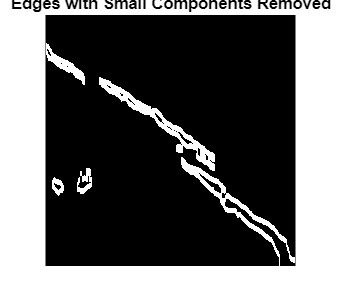


% Remove small components from the edges to reduce false positives
minComponentSize = 500; % Minimum size of components to keep
edges = imdilate(edges, se); % Dilate edges to connect small cracks
edges = bwareaopen(edges, minComponentSize);
imshow(edges);
title("Edges with Small Components Removed");

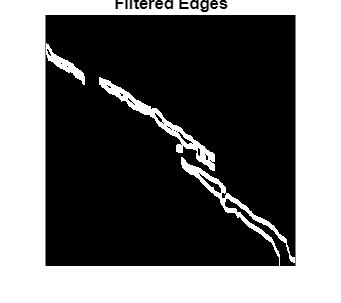


% Further filter edges based on aspect ratio to reduce non-crack detections
labeledImage = bwlabel(edges);
stats = regionprops(labeledImage, 'Area', 'MajorAxisLength', 'MinorAxisLength');

% Filter based on area and aspect ratio
for k = 1 : length(stats)
    % Remove components that are too small or not elongated enough
    if stats(k).Area < minComponentSize || stats(k).MajorAxisLength / stats(k).MinorAxisLength < 2
        edges(labeledImage == k) = 0;
    end
end
imshow(edges);
title("Filtered Edges");

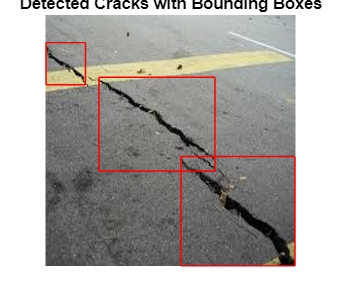


% Detect bounding boxes for the filtered cracks
boundingBoxes = regionprops(edges, 'BoundingBox');

% Display the detected cracks with bounding boxes on the original image
figure, imshow(image), title('Detected Cracks with Bounding Boxes');
hold on;
for k = 1 : length(boundingBoxes)
    rectangle('Position', boundingBoxes(k).BoundingBox, 'EdgeColor', 'r', 'LineWidth', 0.1);
end
hold off;